% parameters
N = 100 ;
standard_err_value = 1e-4;
[p,x_start,t_start,t_stop,max_dt_FE] = getParam_HeatBar(N, 1000);
x0 = sparse(zeros(N,1)); %%% ALso have to play 
timestep = 1e-5;
eval_f = 'eval_f_LinearSystem';
eval_u = 'eval_u_step';
visualize = 0;


% Reference Solution and err_ref DO NOT RUN
[X_ref, t_ref] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,1,visualize);
err_ref = [];
for i=3:5
    timestep = 10^(-i);
    [X,t] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
    err_ref(end + 1) = norm(X(:, end) - X_ref(:, end), Inf);
    X_ref = X;
    t_ref = t;
end
err_ref


save 'reference.mat' X_ref err_ref

% Err_unstable
load reference.mat;
err_unstable = [];
for i=-4:3
    timestep = 10^(-i);
    [X,t] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
    err_unstable(end + 1) = norm(X(:, end) - X_ref(:, end), Inf);
end
err_unstable

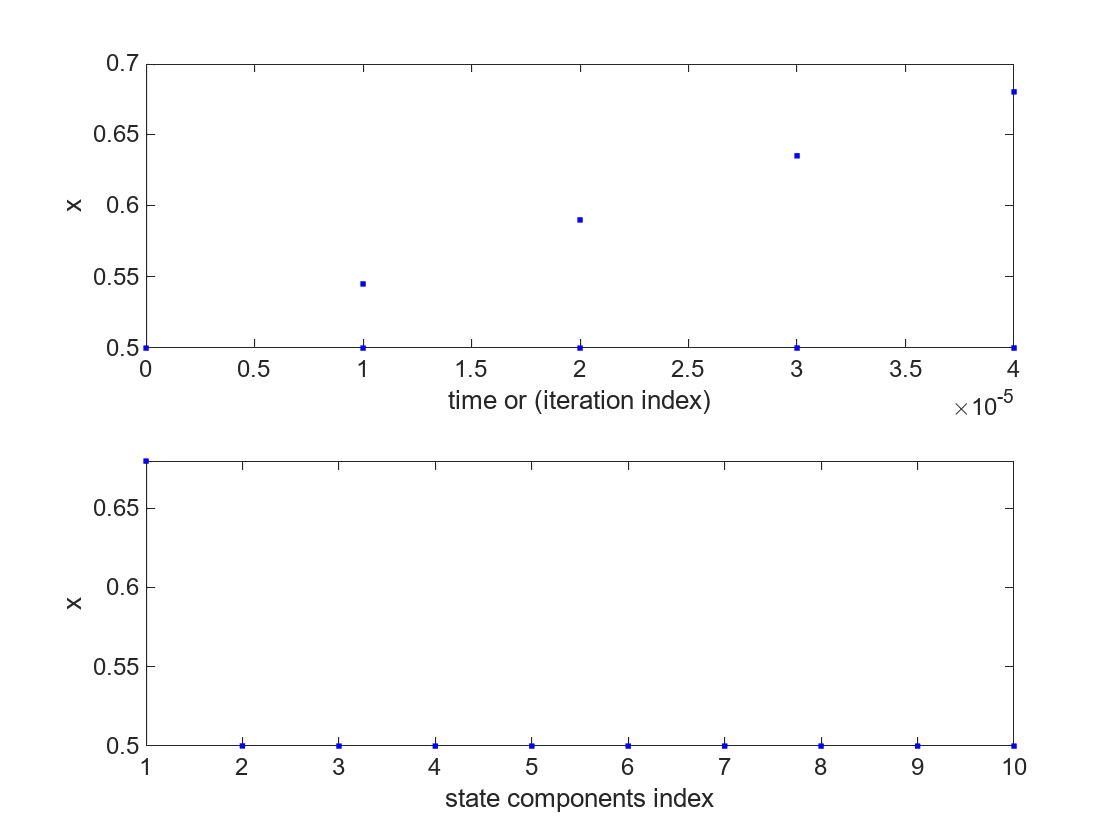

% Dynamic delta_t
clear all
close all
% load reference.mat;
% parameters
N = 10;
standard_err_value = 1e-4;
[p,x_start,t_start,t_stop,max_dt_FE] = getParam_HeatBar(N, 1000);
x0 = sparse(zeros(N,1)); %%% ALso have to play 
timestep = 1e-5;
eval_f = 'eval_f_LinearSystem';
eval_u = 'eval_u_step';
visualize = 0;
timestep = 10^(-5);
t_stop = 0.1; % Remove this Afterwards 
tic;
visualize = 1;
[X_fe,t_fe] = ForwardEuler(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);

toc
disp(X_fe(:, end))
% err_fe = norm(X_fe(:, end) - X_ref(:, end), Inf)

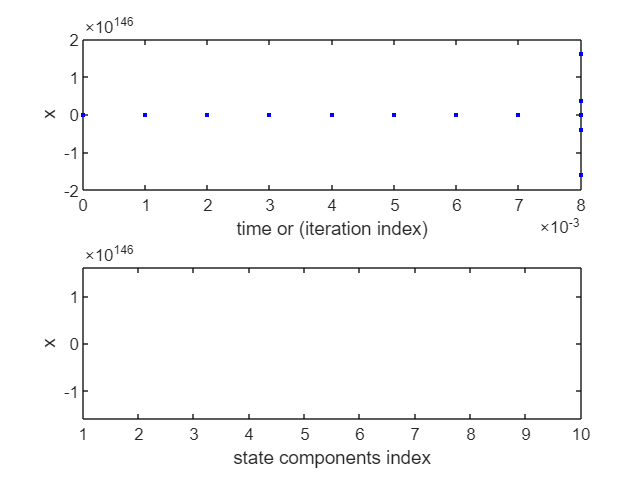

% % Dynamic delta_t
clear all
close all
% load reference.mat;
% parameters
N = 10 ;
standard_err_value = 1e-4;
[p,x_start,t_start,t_stop,max_dt_FE] = getParam_HeatBar(N, 1000);
x0 = sparse(zeros(N,1)); %%% ALso have to play 
% x_start = X_fe(:, end); %REMOVE AFTER
timestep = 1e-5;
eval_f = 'linear_func_always';
eval_u = 'eval_u_step';
visualize = 0;
timestep = 10^(-3);
tic;
visualize = 1;
u=1;
% t_stop = 0.1;
% first_x = eval_f_LinearSystem(x_start,p,u);
% new_p = linearization_function(x_start,p,u); 
[X_fe_linear,t_fe] = ForwardEuler(eval_f,x_start,p ,eval_u,t_start,t_stop,timestep,visualize);

toc
disp(X_fe_linear(:, end))
% err_fe = norm(X_fe(:, end) - X_ref(:, end), Inf)
% tic;
% [X_tr,t_tr] = Trapezoidal_Dynamic(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize, 5);
% toc
% err_trp = norm(X_tr(:, end) - X_ref(:, end), Inf)

% timestep = 10^(-2);
% tic;
% [X_trap,t_trap] = Trapezoidal(eval_f,x_start,p,eval_u,t_start,t_stop,timestep,visualize);
% toc
load reference.mat;
err_trap = norm(X_trap(:, end) - X_ref(:, end), Inf)

err_fe = norm(X_fe(:, end) - X_ref(:, end), Inf)
err_trp = norm(X_tr(:, end) - X_ref(:, end), Inf)

